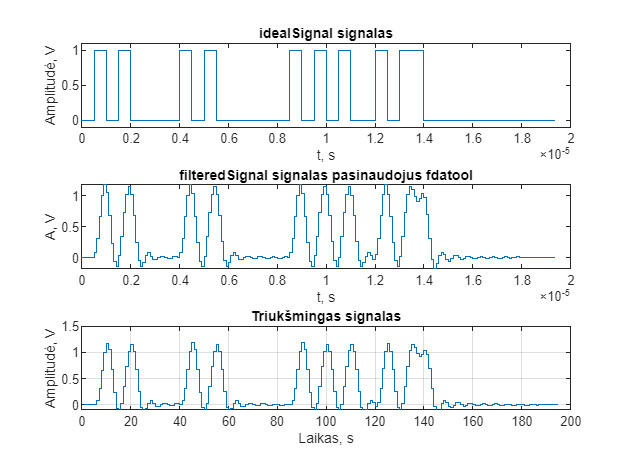

fdiskret = 10E6;
tdiskret = 1/fdiskret;
A = 1;
ADCmax = 1.5;
ADCmin = 0;
ADCbits = pow2(8)-1;

idealOne = [ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret))];
idealZero = [zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret))];


idealPreambule = [ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret))];
idealSignal = [zeros(1, 5), idealPreambule, zeros(1, round(3E-6/tdiskret)), idealOne, idealOne, idealOne, idealZero, idealZero, idealOne, zeros(1, 50)];
%N = 4 * 1 / fsignal * fdiskret;
%n = 0:N-1;
%t = 0:1/fdiskret:1/fdiskret*(N-1);
%s = 2+ A * sin(2 * pi * fsignal * n / fdiskret);
N = length(idealSignal);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);

subplot(3, 1, 1)
stairs(t, idealSignal)
xlabel('t, s')
ylabel('Amplitudė, V')
title('idealSignal signalas')
ylim([-0.1, 1.1])

%Filtro š
load 'FiltroKoef.mat'
filteredSignal = filter(Hd, idealSignal);
subplot(3, 1, 2)
stairs(t, filteredSignal)
title("filteredSignal signalas pasinaudojus fdatool")
xlabel("t, s")
ylabel("A, V")


%Triuksmo generavimas
vid = 0;
std = 0.0;
triuksmas = vid + std*abs(randn(1, N));
triuksmasFiltruotas = filter(Hd, triuksmas);
noisySignal = filteredSignal + triuksmasFiltruotas;
subplot(3, 1, 3)
stairs(noisySignal)
ylabel('Amplitudė, V')
xlabel('Laikas, s')
title('Triukšmingas signalas')
ylim([-0.1, 1.5])
grid on

%Prafiltruojam ir testavimo duomenis
oneone = filter(Hd, [idealOne, idealOne, zeros(1, 15)]);
onezero = filter(Hd, [idealOne, idealZero, zeros(1, 15)]);
zeroone = filter(Hd, [idealZero, idealOne, zeros(1, 15)]);
zerozero = filter(Hd, [idealZero, idealZero, zeros(1, 15)]);

oneone = oneone(2:2+20);
onezero = onezero(2:2+20);
zeroone = zeroone(2:2+20);
zerozero = zerozero(2:2+20);
ADCsignal = round(noisySignal / ADCmax*ADCbits); %1.5V Vref
for i = 1: length(ADCsignal)
    if(ADCsignal(i) > ADCbits)
        ADCsignal(i) = ADCbits;
    elseif(ADCsignal(i) < 0)
        ADCsignal(i) = 0;
    end
end
ADCpreambule = idealPreambule / ADCmax*ADCbits;


%Irasyti failaa
%{
testVoltage = fopen('testVoltage.txt','w');
preambuleVoltage = fopen('idealPreambuleVoltage.txt','w');
idealOne = fopen('idealOneVoltage.txt','w');
idealZero = fopen('idealZeroVoltage.txt','w');
for i = 1:length(ADCsignal)
    temp = dec2bin(ADCsignal(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end
for i = 1:length(ADCpreambule)
    temp = dec2bin(ADCpreambule(i), 8);
    fprintf(preambuleVoltage,'%s\n',temp);
end
for i = 1:length(idealOne)
    temp = dec2bin(idealOne(i), 8);
    fprintf(idealOne,'%s\n',temp);
    temp = dec2bin(idealZero(i), 8);
    fprintf(idealZero,'%s\n',temp);
end
fclose(testVoltage);
fclose(preambuleVoltage);
fclose(idealOne);
fclose(idealZero);
%}
funkcijuFailas = fopen('Conv_func_data.mif','w');
duomenisIrasyti = [ADCpreambule, idealOne, idealZero, idealZero, idealOne, idealZero, idealZero, idealOne, idealOne]; %Praembule, idealOne, idealZero

fprintf(funkcijuFailas, "WIDTH=8;\nDEPTH=%i;\nADDRESS_RADIX=UNS;\nDATA_RADIX=UNS;\nCONTENT BEGIN \n", length(duomenisIrasyti));

for i = 1:length(duomenisIrasyti)
    %temp = dec2bin(duomenisIrasyti(i), 8);
    %fprintf(funkcijuFailas,'%s\n',temp);
    fprintf(funkcijuFailas,'%i : %i;\n',i-1, duomenisIrasyti(i));
end
fprintf(funkcijuFailas, "END;");
fclose(funkcijuFailas);

testVoltage = fopen('testVoltage.txt','w');
for i = 1: length(ADCsignal)
    temp = dec2bin(ADCsignal(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end


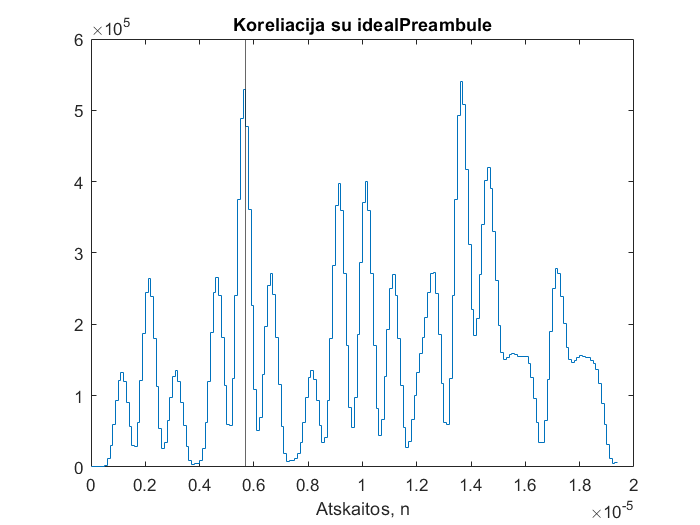

konvoliucija = conv(ADCsignal, ADCpreambule);
figure
stairs(t, konvoliucija(1:length(ADCsignal)))
xline(5.7E-6);
title('Koreliacija su idealPreambule')
xlabel('Atskaitos, n')

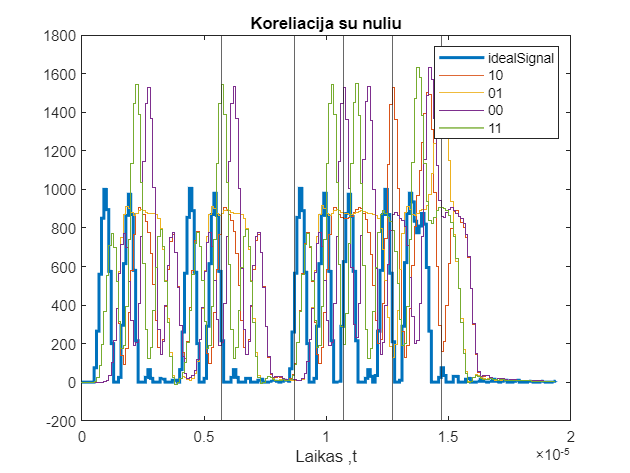


stairs(t, ADCsignal*5, 'LineWidth',2)
hold on
%konvoliucija1 = conv(ADCsignal, idealOne);
%plot(t, konvoliucija1(1:length(ADCsignal)))
title('Koreliacija su vienetu')
xlabel('Atskaitos, n')

%konvoliucija2 = conv(ADCsignal, idealZero);
%plot(t, konvoliucija2(1:length(ADCsignal)))
title('Koreliacija su nuliu')
xlabel('Laikas ,t')
konvoliucija3 = conv(ADCsignal, onezero);
stairs(t, konvoliucija3(1:length(ADCsignal)))

konvoliucija4 = conv(ADCsignal, zeroone);
stairs(t, konvoliucija4(1:length(ADCsignal)))

konvoliucija5 = conv(ADCsignal, zerozero);
stairs(t, konvoliucija5(1:length(ADCsignal)))

konvoliucija6 = conv(ADCsignal, oneone);
stairs(t, konvoliucija6(1:length(ADCsignal)))

xline(5.7E-6);
xline(5.7E-6+3E-6);
xline(5.7E-6+3E-6+2E-6);
xline(5.7E-6+3E-6+4E-6);
xline(5.7E-6+3E-6+6E-6);

%xline(117/fdiskret, 'color','green');
%xline(138/fdiskret, 'color','green');
%xline(159/fdiskret, 'color','green');

legend("idealSignal", "10", "01", "00", "11")

hold off

[amplitude, vieta] = max(konvoliucija) %15 uzvelina

amplitude = 541110

vieta = 137

vietaLaike = vieta / fdiskret %1.34us uzvelina

vietaLaike = 1.3700e-05

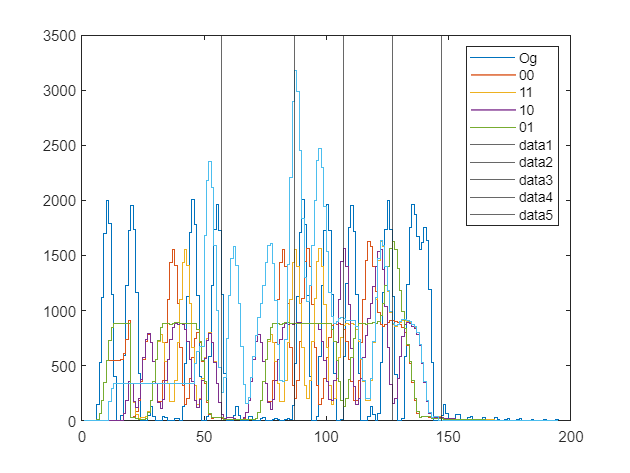


n11 = GenerateConv(ADCsignal, [idealOne, idealOne]);
n00 = GenerateConv(ADCsignal, [idealZero, idealZero]);
n01 = GenerateConv(ADCsignal, [idealZero, idealOne]);
n10 = GenerateConv(ADCsignal, [idealOne, idealZero]);
np = GenerateConv(ADCsignal, idealPreambule);

stairs(ADCsignal*10)
hold on
stairs(n00)
stairs(n11)
stairs(n10)
stairs(n01)
stairs(np)

legend("Og", "00", "11", "10", "01")

xline((5.7E-6)*fdiskret);
xline((5.7E-6+3E-6)*fdiskret);
xline((5.7E-6+3E-6+2E-6)*fdiskret);
xline((5.7E-6+3E-6+4E-6)*fdiskret);
xline((5.7E-6+3E-6+6E-6)*fdiskret);
hold off

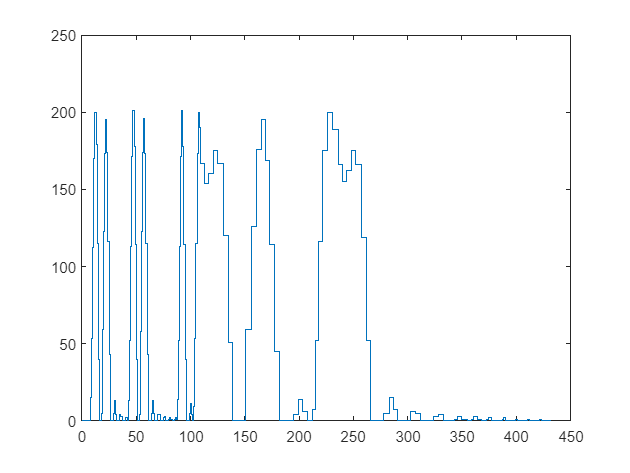

%IMIMAS IS MODELSIMO
msfile = fopen('modelsimData.txt','r');
pliusas = char(43);
formatSpec = ['%d %d %d %d %d %d %d %d'];

msdata = fscanf(msfile,formatSpec, [8 Inf]);

% time +4 arrIndex  adcout 00 01 10 11

for i = 1:length(msdata(4, :))
    msdata(4, i) = bin2dec(string(msdata(4, i)));
end

figure
stairs(msdata(4, :))

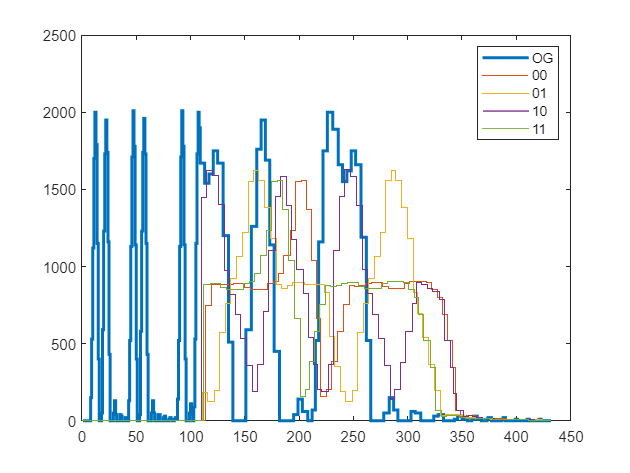


figure
stairs(msdata(4, :)*10, 'LineWidth',2)
hold on
stairs(msdata(5, :))
stairs(msdata(6, :))
stairs(msdata(7, :))
stairs(msdata(8, :))
legend("OG", "00", "01", "10", "11")

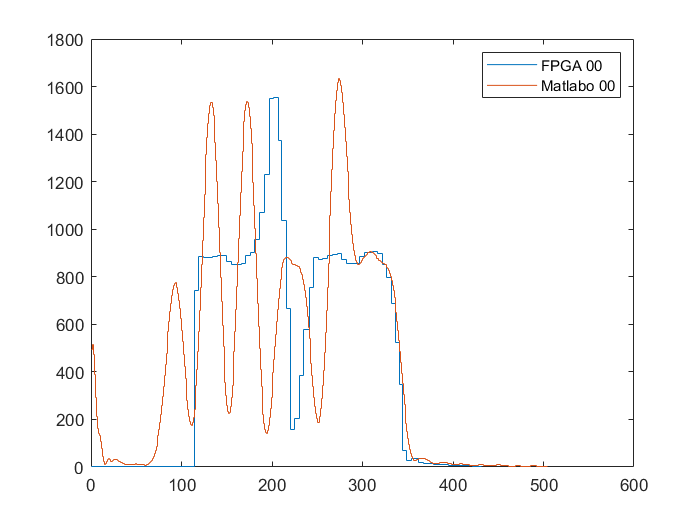


figure

stairs(msdata(5, :))
hold on
stairs(resample(konvoliucija5(75:200), 4, 1))
legend( "FPGA 00", "Matlabo 00")
hold off

function y = GenerateConv(a, b)
    y = zeros(1, length(a));
    for i = 1:length(a)-length(b)
        if(i < length(b))
            testArr = [b(1:i), zeros(1, length(a)- i)];
        else
            testArr = [zeros(1, i), b, zeros(1, length(a)-length(b) - i)];
        end
        length(testArr);
        y(i) = sum(a.*testArr);
    end
end

